# EE6133 : Multirate Digital Signal Processing

# Assignment 2b

## Name : ANIRUDH B S (EE21B019)

## Magnitude Response of the Unprocessed Music Signal

Firstly, I will plot the Magnitude Spectrum of the Music Signal sampled at 16 kHz.

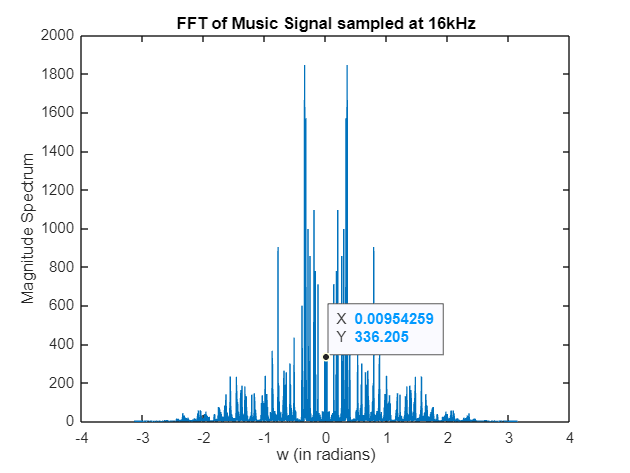

[xm,Fs] = audioread("music16khz.wav");
Lm = 160000;
Xm = fft(xm);
Xm = fftshift(Xm);
wm = (-Lm/2:Lm/2-1) * (2*pi/Lm);
plot(wm,abs(Xm));
title('FFT of Music Signal sampled at 16kHz')
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(xm,Fs);

## C and D Matrices

In this fragment of the code, I will extract the values of C and D from the csv file named 'D.csv'

D_matrix = csvread('D.csv');
D_matrix = D_matrix(:, 1:end-1);
D_row = reshape(D_matrix', 1, []);
D_col = D_row(1:512);
C_col = D_col/32;
D = D_col';
C = C_col';

## Case 1 : $\theta_k = -\frac{(2k+1)\pi}{64}$ as per the MP3 specification.

## M Matrix for Analysis

In the below fragment, I will derive matrix M which will be used for Analysis later.

M = zeros(32, 64);
for i=1:32 
    M(i,:) = cos((2*i-1)*([0:63]-16)*pi/64); %theta_k as per MP3 spec.
end

## N Matrix for Synthesis

In the below fragment, I will derive matrix N which will be used for Synthesis later.

N = zeros(64, 32);
for i=1:64 
    N(i,:) = cos((2*[0:31]+1)*(i+15)*pi/64); %theta_k as per MP3 spec.
end

## Analysis Operation

The below snippet executes the Analysis Flowchart.

function [ana, X_new] = analysis(input, X, C, M)
    X(33:end) = X(1:end-32);
    for i=1:32 
        X(i)=input(33-i);
    end
    Z = C .* X;
    Y = zeros(64,1);
    for i=1:64
        Y(i) = Z(i+64*0) + Z(i+64*1) + Z(i+64*2) + Z(i+64*3) + Z(i+64*4) + Z(i+64*5) + Z(i+64*6) + Z(i+64*7);
    end
    S = M * Y;
    ana = S;
    X_new = X;
end

## Synthesis Operation

The below snippet executes the Synthesis Flowchart.

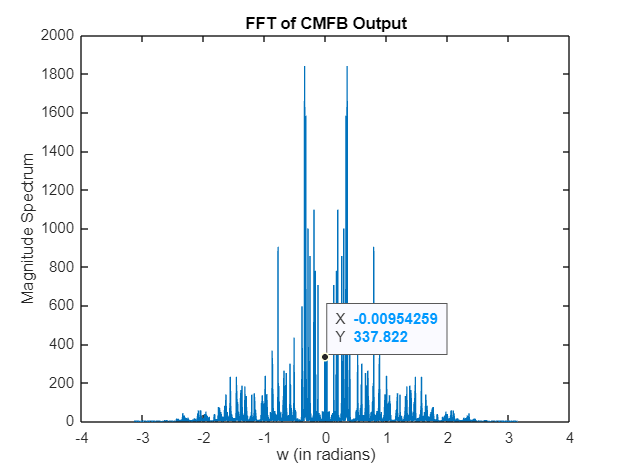

function [syn, U_new, V_new] = synthesis(input_data, U, V, D, N)
    V(65:end) = V(1:end-64);
    V(1:64) = N * input_data;
    for i=1:8
        for j=1:32
             U((i-1)*64+(j-1)+1) = V((i-1)*128+(j-1)+1);
             U((i-1)*64+32+(j-1)+1) = V((i-1)*128+96+(j-1)+1);

        end
    end
    W = D .* U;
    S = zeros(32,1);
    for i=1:32 
        S(i) = W(i+32*0) + W(i+32*1) + W(i+32*2) + W(i+32*3) + W(i+32*4) + W(i+32*5) + W(i+32*6) + W(i+32*7) + W(i+32*8) + W(i+32*9) + W(i+32*10) + W(i+32*11) + W(i+32*12) + W(i+32*13) + W(i+32*14) + W(i+32*15);
    end
    syn = S;
    U_new = U;
    V_new = V;
end

## Executing the MP3 Flowchart

The code is executed on input music file sampled at 16 kHz.

leng = (size(xm,1))/32;
analysis_op = zeros(size(xm,1),1);
X = zeros(512,1);
for i=1:leng
    inp_analysis = xm(1+(i-1)*32:32+(i-1)*32);
    [analysis_op(1+(i-1)*32:32+(i-1)*32), X] = analysis(inp_analysis, X, C, M);
end
synthesis_op = zeros(size(xm,1),1);
U = zeros(512,1);
V = zeros(1024,1);
for i=1:leng
    inp_synthesis = analysis_op(1+(i-1)*32:32+(i-1)*32);
    [synthesis_op(1+(i-1)*32:32+(i-1)*32), U, V] = synthesis(inp_synthesis, U, V, D, N);
end

## Frequency Response of the Output

yo = synthesis_op;
Yo = fft(yo);
Yo = fftshift(Yo);
plot(wm,abs(Yo));
title('FFT of CMFB Output');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');
sound(yo,Fs);
audiowrite('CMFBOutput.wav', yo, Fs);

## Observation

The output more or less resembles the input when $\theta_k = -\frac{(2k+1)\pi}{64}$

- The magnitude spectrum is almost identical to the input spectrum. 

- The output audio is almost exactly similar to the input audio. 

## Case 2 : $\theta_k = 0$ to investigate the output

In this case, matrices M and N get modified as follows - 

## Modified M Matrix for Analysis

In the below fragment, I will derive matrix M which will be used for Analysis later.

M = zeros(32, 64);
for i=1:32 
    M(i,:) = cos((2*i-1)*([0:63])*pi/64); %theta_k = 0
end

## Modified N Matrix for Synthesis

In the below fragment, I will derive matrix N which will be used for Synthesis later.

N = zeros(64, 32);
for i=1:64 
    N(i,:) = cos((2*[0:31]+1)*(i-1)*pi/64); %theta_k = 0
end

## Executing the MP3 Flowchart for Modified M and N

The code is executed on input music file sampled at 16 kHz.for Modified M and N. 

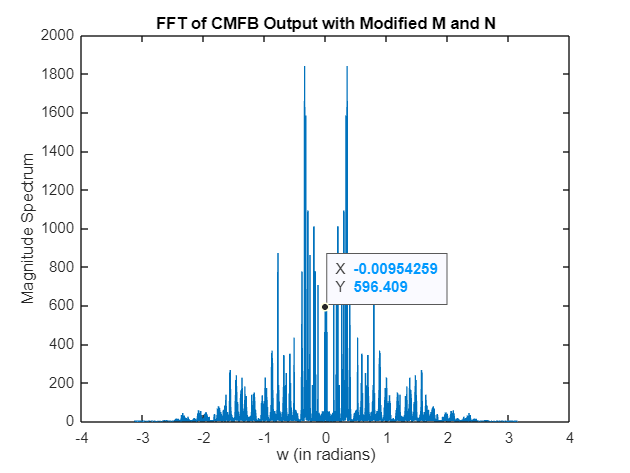

leng = (size(xm,1))/32;
analysis_op_x = zeros(size(xm,1),1);
X = zeros(512,1);

for i=1:leng
    inp_analysis = xm(1+(i-1)*32:32+(i-1)*32);

    [analysis_op_x(1+(i-1)*32:32+(i-1)*32), X] = analysis(inp_analysis, X, C, M);
end
synthesis_op_x = zeros(size(xm,1),1);
U = zeros(512,1);
V = zeros(1024,1);
for i=1:leng
    inp_synthesis = analysis_op_x(1+(i-1)*32:32+(i-1)*32);
    [synthesis_op_x(1+(i-1)*32:32+(i-1)*32), U, V] = synthesis(inp_synthesis, U, V, D, N);
end

## Frequency Response of the Output

y1 = synthesis_op_x;
Y1 = fft(y1);
Y1 = fftshift(Y1);
plot(wm,abs(Y1));
title('FFT of CMFB Output with Modified M and N');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');
sound(y1,Fs);
audiowrite('CMFBOutputNew.wav', y1, Fs);

## Observation

The output more or less resembles the input when $\theta_k = 0$

- The magnitude spectrum is similar to the input and previous output, except near $\omega = 0$. There is aliasing near  $\omega = 0$.

- The output audio is almost similar to the input audio and the previous output. 